clc;
clear;
close all;

serialPort = 'COM9';
baudRate = 1024000;

s = serialport(serialPort, baudRate);

s.DataBits = 8;
s.StopBits = 1;
s.Parity = 'none';

sensorData = cell(12, 1);

for i = 1:12
    sensorData{i} = [];  
end

disp('开始接收数据...');

开始接收数据...


startTime = tic;  % 记录起始时间

while true

    dataBytes = read(s, 36 * 4, 'uint8');
    
    if numel(dataBytes) ~= 36 * 4
        warning('数据长度异常，跳过当前循环');
        continue;
    end
    
    timestamp = toc(startTime);
    

    dataFloats = typecast(uint8(dataBytes), 'single');
    
    
    for i = 1:12
        x = dataFloats(3*i-2);
        y = dataFloats(3*i-1);
        z = dataFloats(3*i);
        sensorData{i} = [sensorData{i}; timestamp, x, y, z];  % 追加数据
    end
    
    disp(['传感器 1 数据: ', num2str(sensorData{1}(end, :))]);

    % 手动终止：Ctrl+C
    if false  
        break;
    end
    
    pause(0.01);
end

传感器 1 数据: 0.0175831       -61.65        20.55         45.3
传感器 1 数据: 0.049145       -60.75        21.15        45.15
传感器 1 数据: 0.080728       -60.75        22.05         45.9
传感器 1 数据: 0.113557       -60.75        20.85         46.2
传感器 1 数据: 0.144241       -60.45        21.15        45.75
传感器 1 数据: 0.161206        -60.3         21.6         45.9
传感器 1 数据: 0.18117        -60.6         20.1         45.6
传感器 1 数据: 0.196201       -60.15        21.45         45.6
传感器 1 数据: 0.211324       -61.65        21.15         45.6
传感器 1 数据: 0.22716        -61.2         21.3        46.35
传感器 1 数据: 0.241287        -60.9         21.6        46.35
传感器 1 数据: 0.257506       -59.85        21.75        45.75
传感器 1 数据: 0.290501        -62.1         21.6         44.7
传感器 1 数据: 0.303384       -60.45        20.85         46.5
传感器 1 数据: 0.336498       -60.75        21.15         46.5
传感器 1 数据: 0.366417       -60.75        22.35        45.45
传感器 1 数据: 0.382035        -61.2           21        45.45
传感器 1 数据: 0.412

%% 关闭串口
clear s;
disp('数据接收完成，开始绘图...');

数据接收完成，开始绘图...


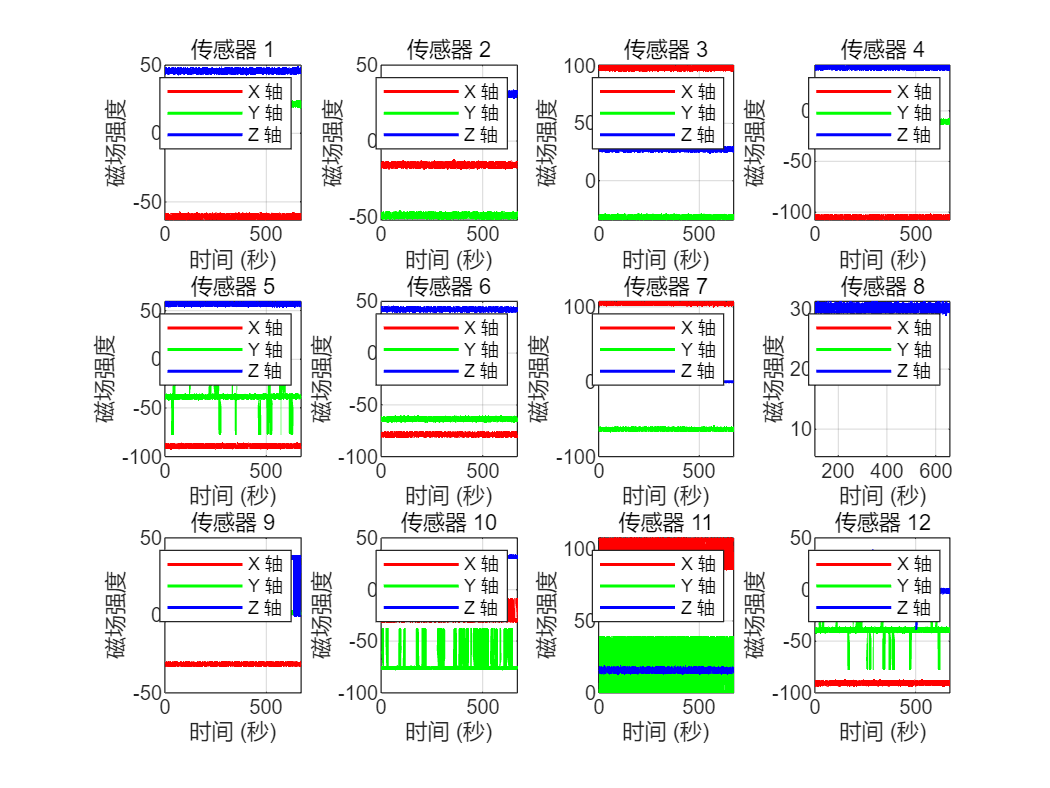



figure;
for i = 1:12
    if isempty(sensorData{i})
        continue; % 跳过没有数据的传感器
    end
    
    % 读取数据
    time = sensorData{i}(:,1); % 时间戳
    xData = sensorData{i}(:,2); % X 轴
    yData = sensorData{i}(:,3); % Y 轴
    zData = sensorData{i}(:,4); % Z 轴
    
    % 绘制子图
    subplot(3, 4, i);
    plot(time, xData, 'r', 'LineWidth', 1.2); hold on;
    plot(time, yData, 'g', 'LineWidth', 1.2);
    plot(time, zData, 'b', 'LineWidth', 1.2);
    
    % 标注
    xlabel('时间 (秒)');
    ylabel('磁场强度');
    title(['传感器 ', num2str(i)]);
    legend('X 轴', 'Y 轴', 'Z 轴');
    grid on;
end

绘图完成！


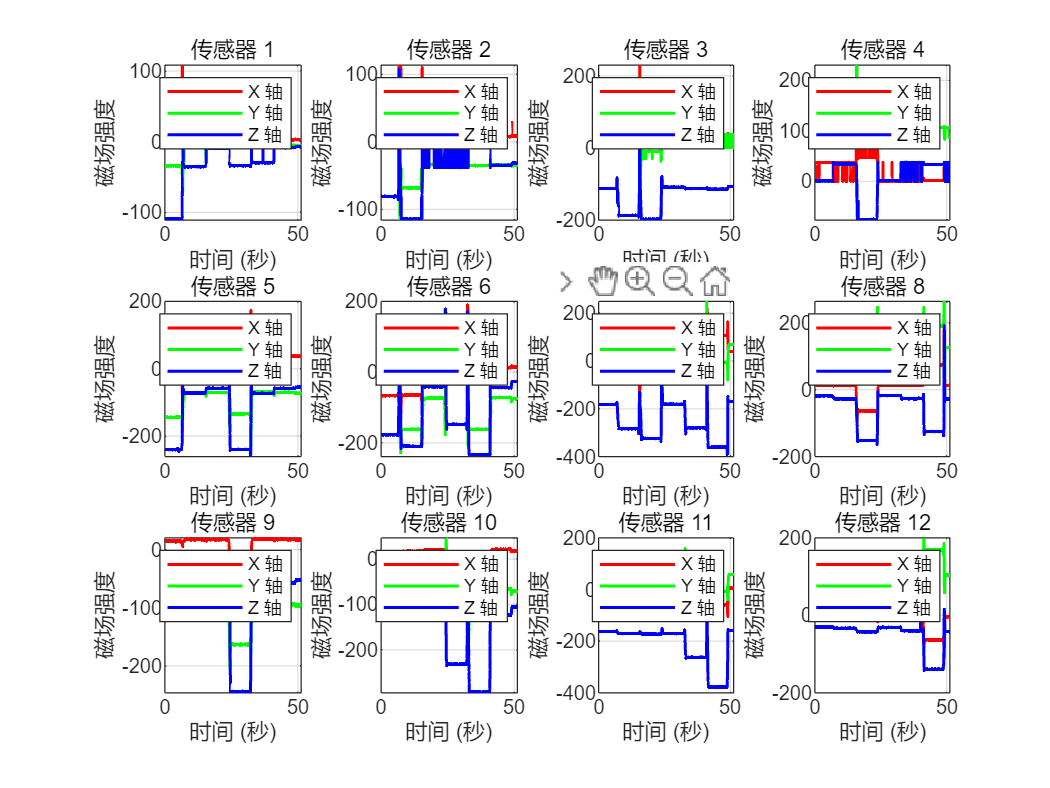


disp('绘图完成！');